# Simulation of ground acceleration record

 Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

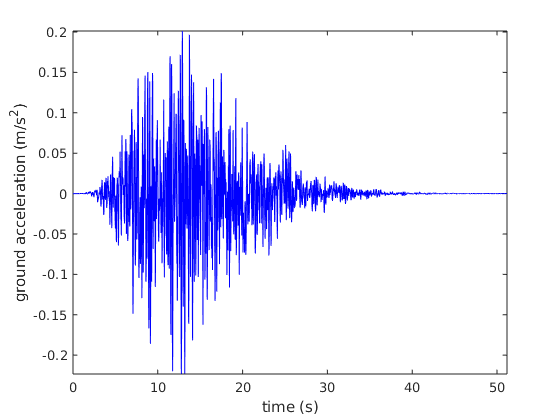

clearvars;close all;clc;

f = linspace(0,40,2048); % frequency vector
zeta = 0.3; % bandwidth of the earthquake excitation.
sigma = 0.3; % standard deviation of the excitation.
fn =5; % dominant frequency of the earthquake excitation (Hz).
T90 = 0.3; % value of the envelop function at 90 percent of the duration.
eps = 0.4; % normalized duration time when ground motion achieves peak.
tn = 30; % duration of ground motion (seconds).

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

figure
plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

set(gcf,'color','w')

## Fitting the ground acceleratoin record to target spectra & envelop

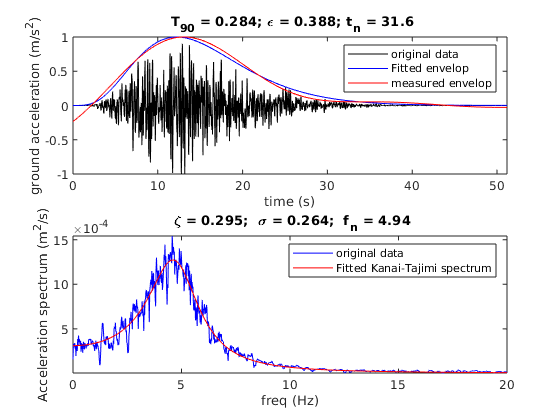

guessEnvelop=[0.33,0.43,50]; % guest for envelop 
guessKT = [1,1,5]; % guess for spectrum
[T90,eps,tn,zeta,sigma,fn] = fitKT(t,y,guessEnvelop,guessKT,...
    'dataPlot','yes');